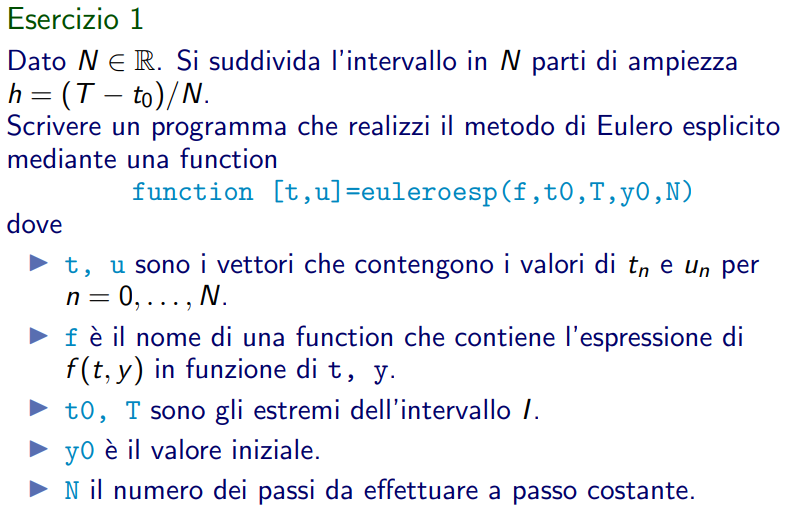

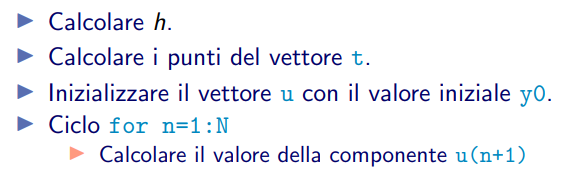

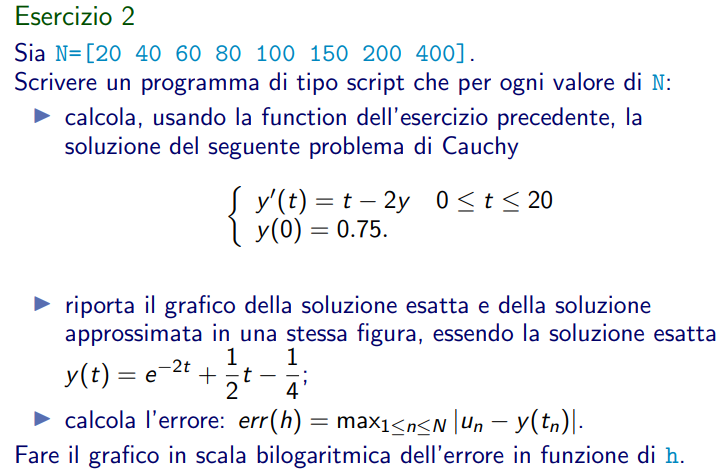

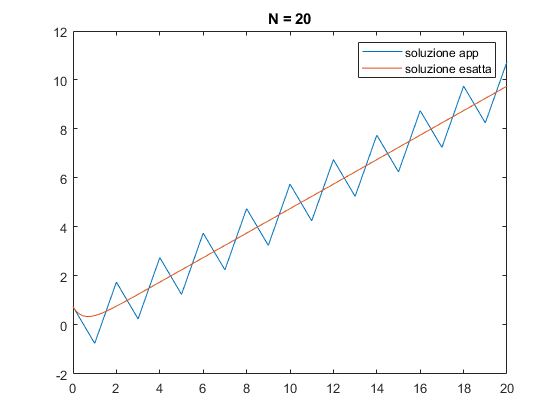

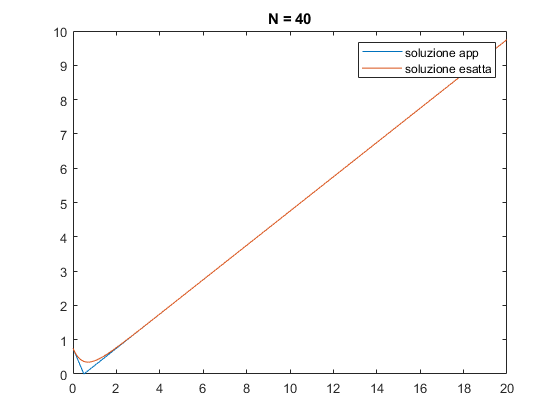

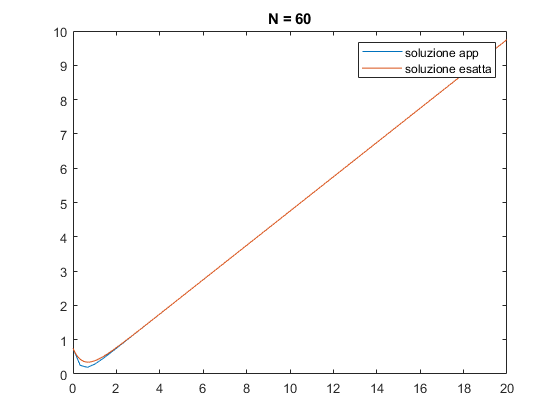

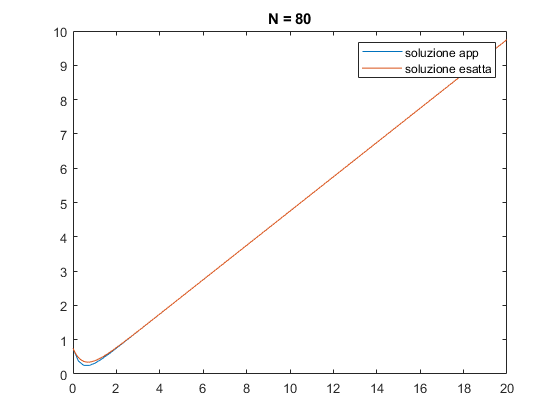

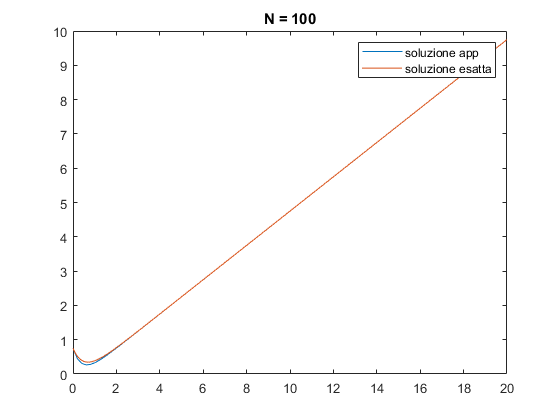

clear all
close all
f = @(t,y) t-2.*y;
t0 = 0;
y0= 0.75;
tm = [0 20];
yt = @(t) exp(-2.*t)+ 0.5.*t -1/4;
N = [20 40 60 80 100 150 200 400];
H = [];
err = [];
for n = N
    [tn,un,h] = euleroesp(f,tm(1),tm(2),y0,n);
    figure()
    plot(tn,un)
    hold on 
    fplot(yt,tm)
    title("N = " +n)
    legend('soluzione app','soluzione esatta')
    hold off
    H = [H h];
    err = [err max(abs(un-yt(tn)))];
end

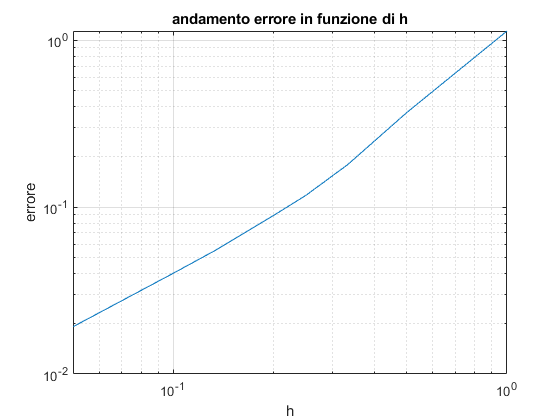

loglog(H,err)
title('andamento errore in funzione di h')
xlabel('h')
ylabel('errore')
grid on

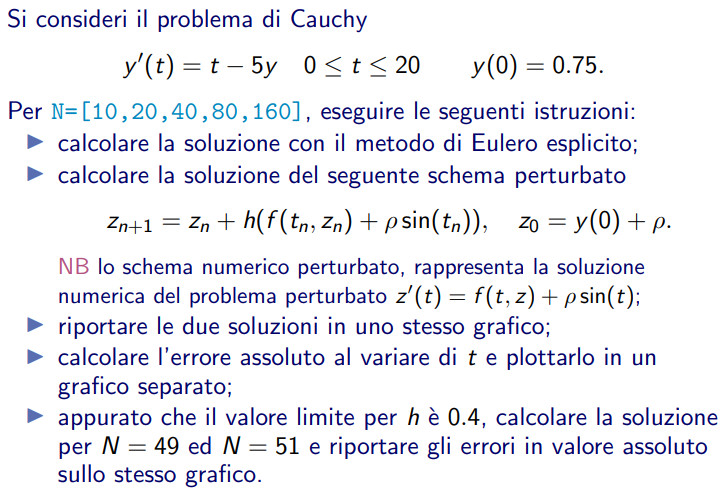

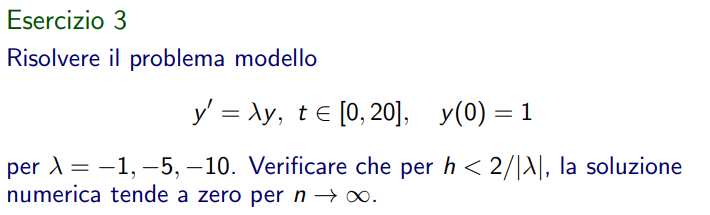

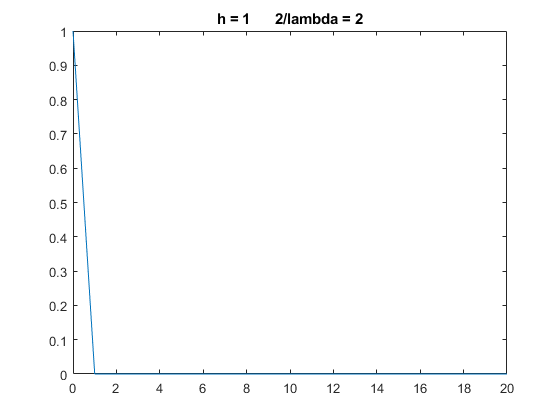

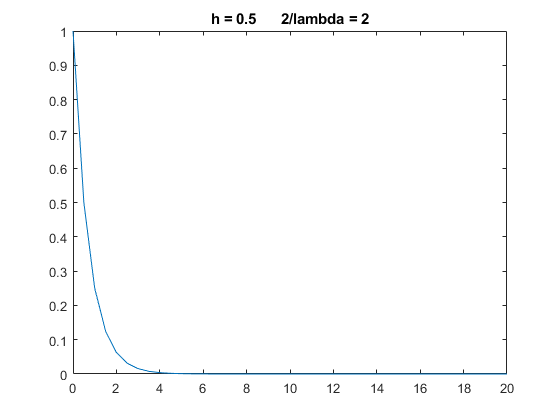

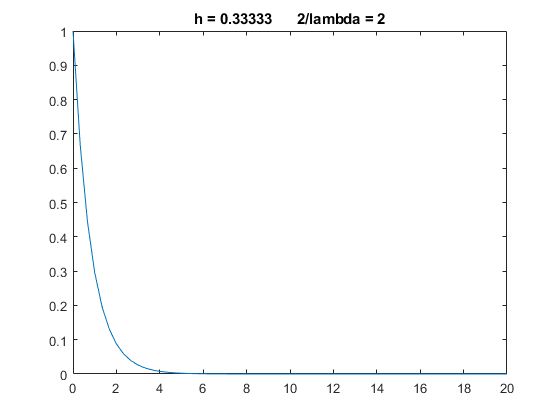

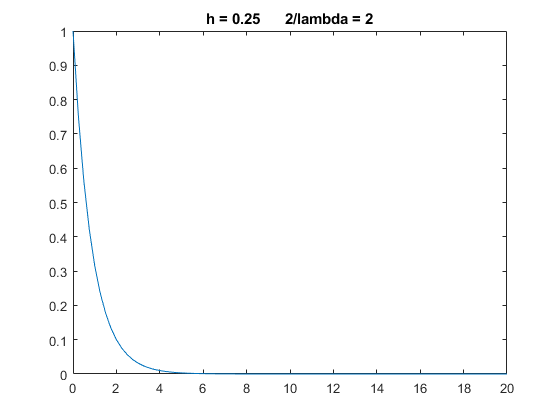

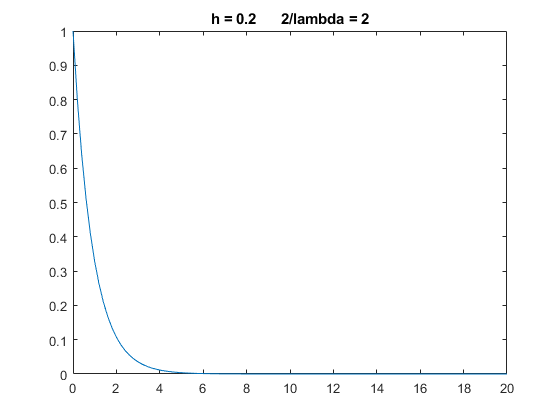

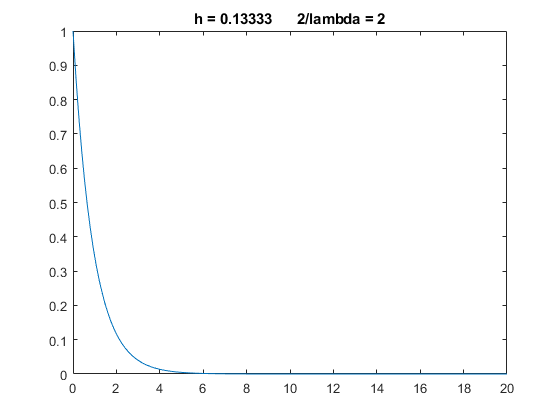

l = [-1 -5 -10];
N = [20 40 60 80 100 150 200 400];
tm =[0 20];
y0 = 1;

for lambda = l
    f = @(t,y) lambda.*y;
    for n = N  
        [tn,un,h] = euleroesp(f,tm(1),tm(2),y0,n);
        figure
        plot(tn,un)
        title("h = " + h + "      2/lambda = "+2/abs(lambda))
    end
end

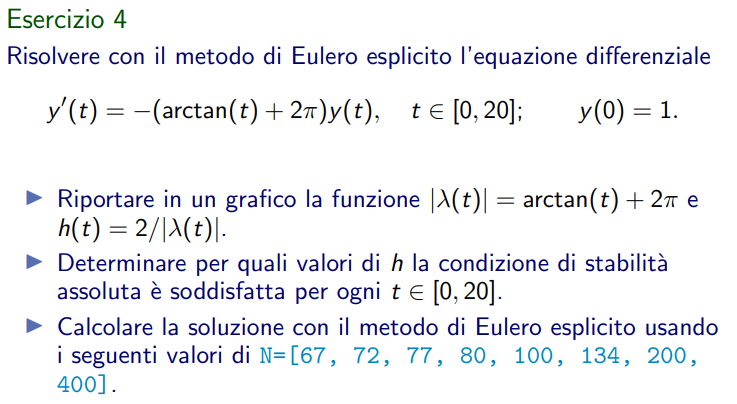

clear all
close all
N = [67 72 77 80 100 134 200 400];
f = @(t,y) -(atan(t)+2*pi).*y;
tm = [0 20];
y0 = 1;
lambda = @(t) atan(t)+2*pi;
h = @(t) 2/abs(atan(t)+2*pi);

figure()
fplot(h,tm)

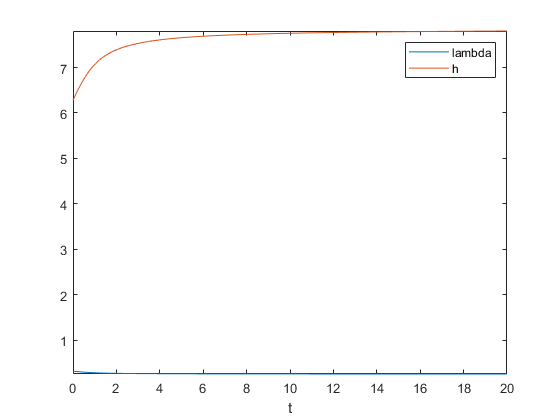

hold on
fplot(lambda,tm)
legend("lambda","h")
xlabel("t")
hold off


figure()
fplot(h,tm)%limite del valore di h per la stabiltà 

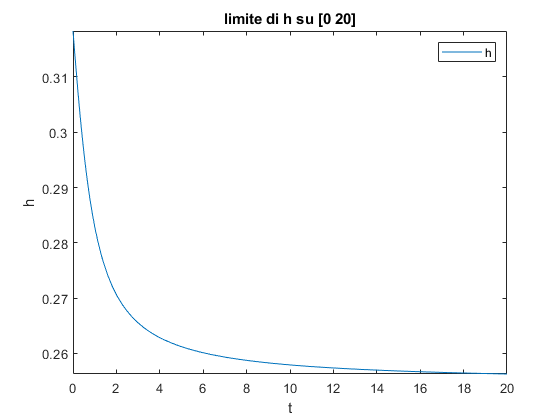

title("limite di h su [0 20]")
legend("h")
xlabel("t")
ylabel("h")

disp("valore limite nell'intervallo [0 20] pari a h = " + h(20))

valore limite nell'intervallo [0 20] pari a h = 0.25628


disp("N limite per convergere = " + (tm(2)-tm(1))/h(20) )

N limite per convergere = 78.0402


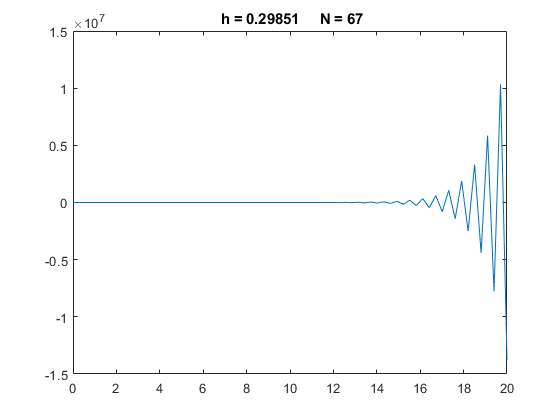

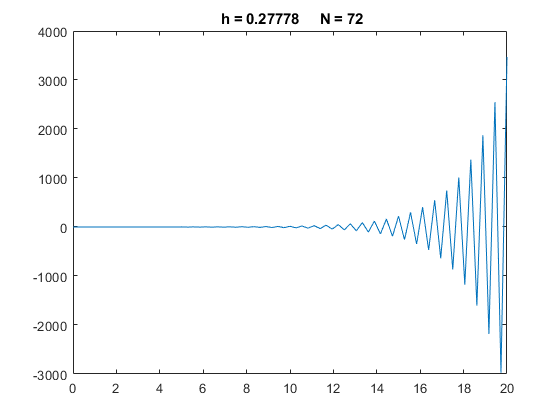

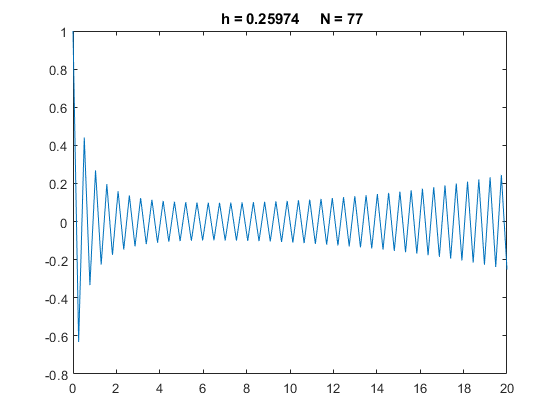

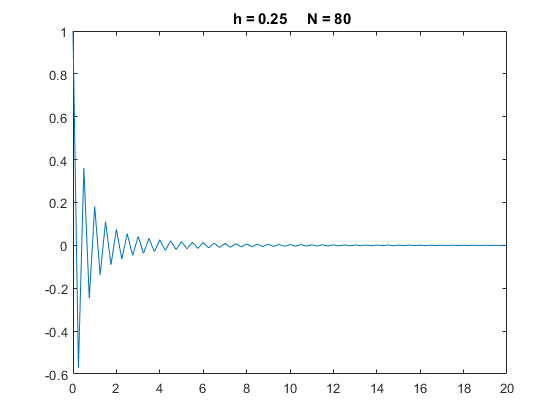

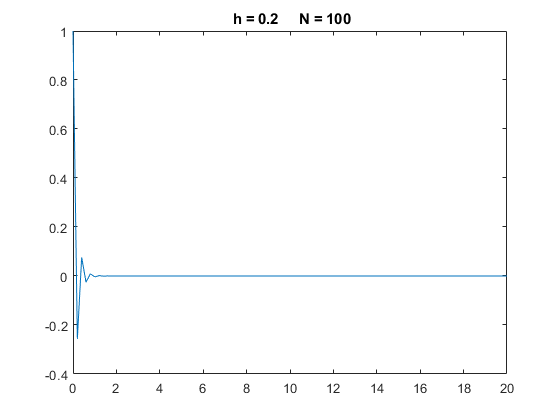

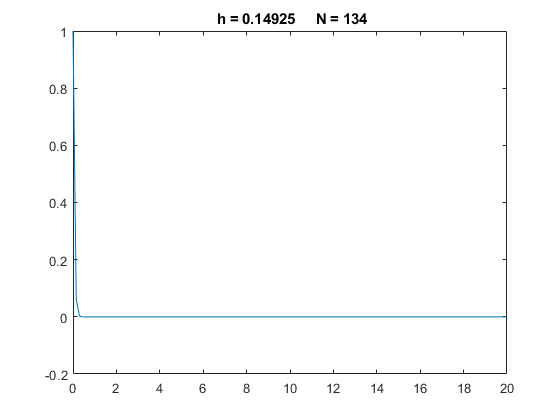

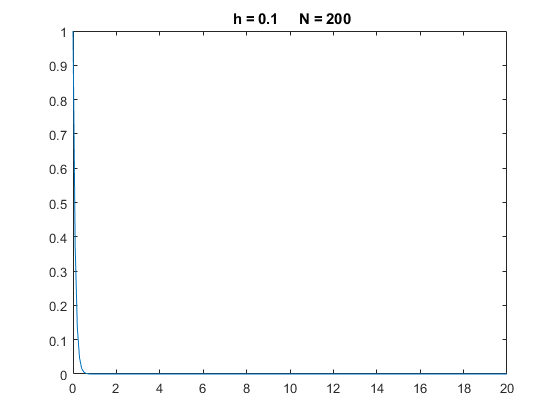

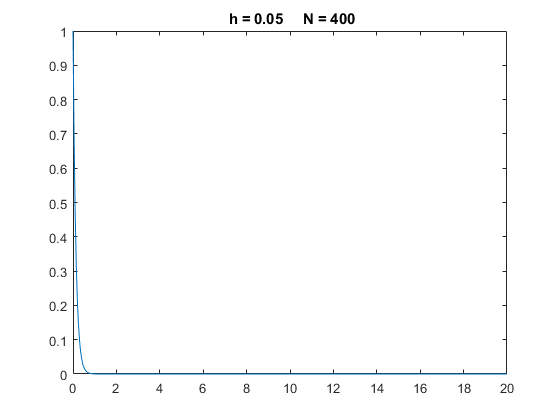

% valori limite sopra ai quali ho la stabilita della soluzione
for n = N
    [tn,un,h] = euleroesp(f,tm(1),tm(2),y0,n);
    figure
    plot(tn,un)
    title(" h = " +h+ "     N = "+ n)
end

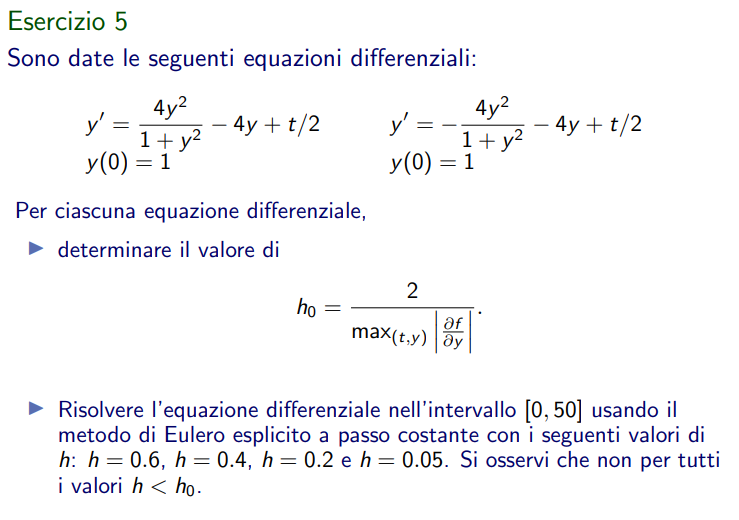

clear all
close all
tm = [0 50];
h1 = [0.6 0.4 0.2 0.05];
N = tm(2)./h1;
y0 = 1;


syms y t
f = (4*y.^2)/(1+y.^2) -4*y + t/2

$$f = \frac{t}{2}-4\,y+\frac{4\,y^{2}}{y^{2}+1}$$

f_ = diff(f) 

$$f\_ = \frac{8\,y}{y^{2}+1}-\frac{8\,y^{3}}{{\left(y^{2}+1\right)}^{2}}-4$$

f_ =matlabFunction(f_)

f_ = function_handle with value:
    @(y)(y.*8.0)./(y.^2+1.0)-y.^3.*1.0./(y.^2+1.0).^2.*8.0-4.0

fplot(f_)
[y,fval]= fminsearch(f_,-10)

y = -0.5773

fval = -6.5981

h0 = 2/abs(fval)

h0 = 0.3031


f = @(t,y) (4*y.^2)/(1+y.^2) -4*y + t/2

f = function_handle with value:
    @(t,y)(4*y.^2)/(1+y.^2)-4*y+t/2

for n = N
    [tn,un,h] = euleroesp(f,tm(1),tm(2),y0,n);
    figure()
    plot(tn,un)
    title("valore di h = " +  h)
    xlabel("t")
    legend("soluzione")
end

syms y 
f = -(4*y.^2)/(1+y.^2) -4*y 

$$f = -4\,y-\frac{4\,y^{2}}{y^{2}+1}$$

f_ = diff(abs(f)) 

$$f\_ = \mathrm{sign}\left(4\,y+\frac{4\,y^{2}}{y^{2}+1}\right)\,\left(\frac{8\,y}{y^{2}+1}-\frac{8\,y^{3}}{{\left(y^{2}+1\right)}^{2}}+4\right)$$

f_ =matlabFunction(f_)

f_ = function_handle with value:
    @(y)sign(y.*4.0+(y.^2.*4.0)./(y.^2+1.0)).*((y.*8.0)./(y.^2+1.0)-y.^3.*1.0./(y.^2+1.0).^2.*8.0+4.0)

figure
fplot(f_,[0 50])
[y,fval]= fminsearch(f_,5)

y = 2.6215e+05

fval = 4

h0 = 2/abs(fval)

h0 = 0.5000


f = @(t,y) -(4*y.^2)/(1+y.^2) -4*y + t/2

f = function_handle with value:
    @(t,y)-(4*y.^2)/(1+y.^2)-4*y+t/2


for n = N
    [tn,un,h] = euleroesp(f,tm(1),tm(2),y0,n);
    figure()
    plot(tn,un)
    title("valore di h = " +  h)
    xlabel("t")
    legend("soluzione")
end


# eulero implicito

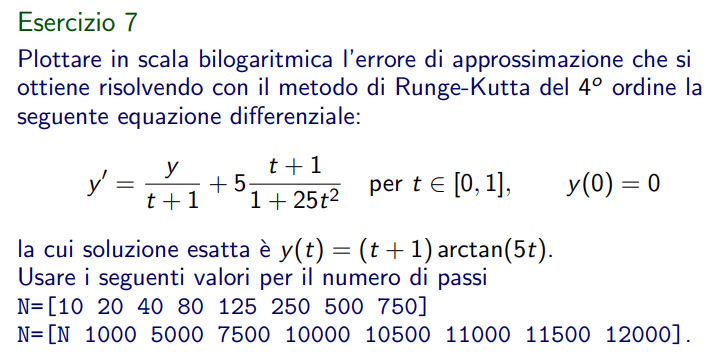

clear all
close all
f =@(t,y) y./(t+1) + 5*(t+1)/(1+25.*t.^2)

f = function_handle with value:
    @(t,y)y./(t+1)+5*(t+1)/(1+25.*t.^2)

Tm = [0 1];
y0 = 0;
y = @(t) (t+1).*atan(5*t);
N = [10 20 40 80 125 250 500 750 1000 5000 7500 10000 10500 11000 11500 12000];
err = zeros(1,length(N))

err =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for n = 1:1:length(N)
   [tn,un] = RK4(f,Tm(1),Tm(2),y0,N(n));
   err(n) = max(abs(y(tn)-un)); 
end
loglog(N,err)
title("andamnto errore in funzione di N")
xlabel("x")

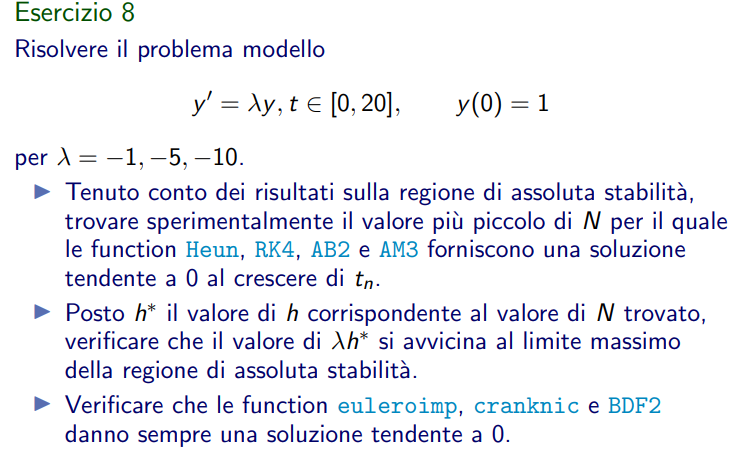

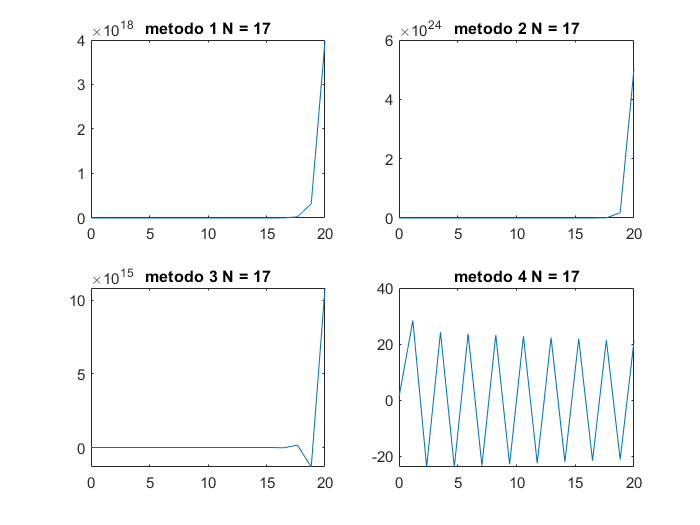

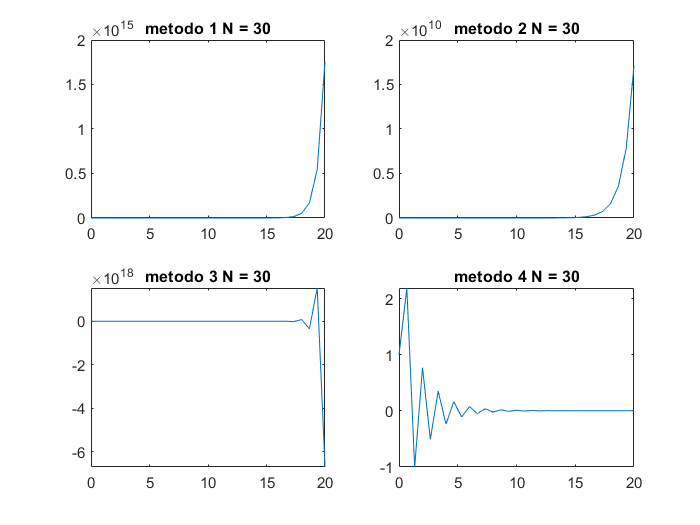

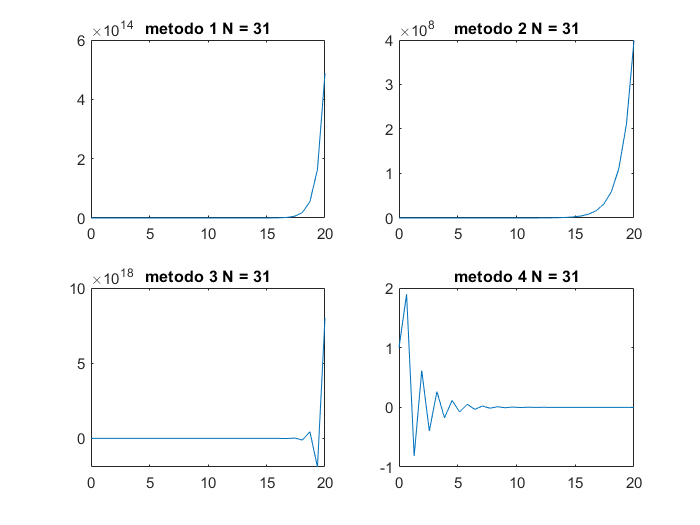

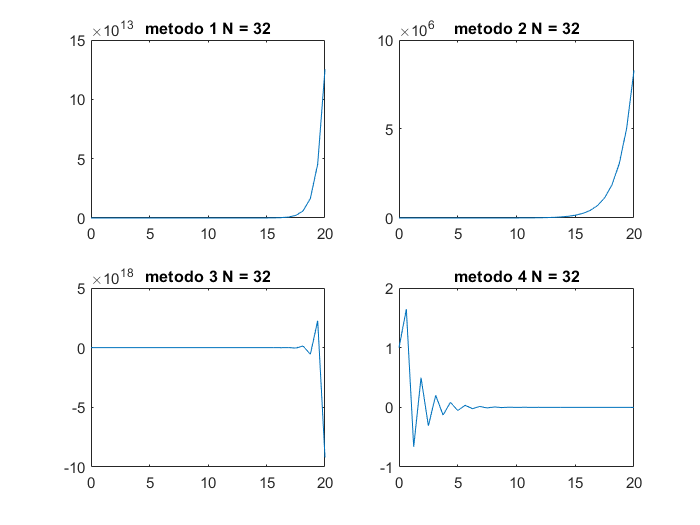

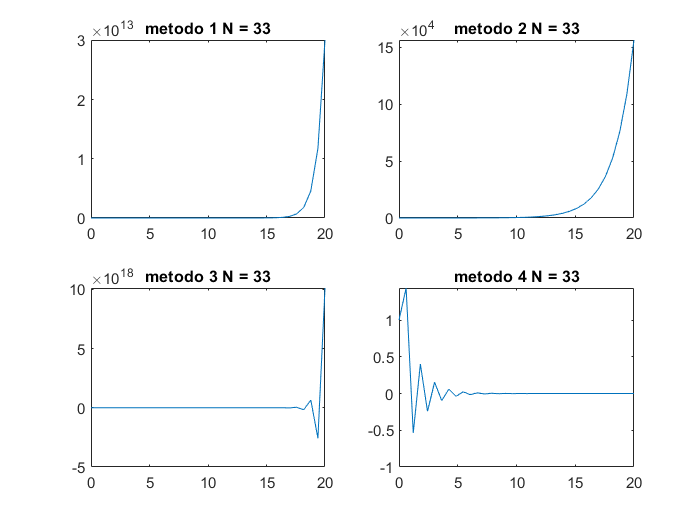

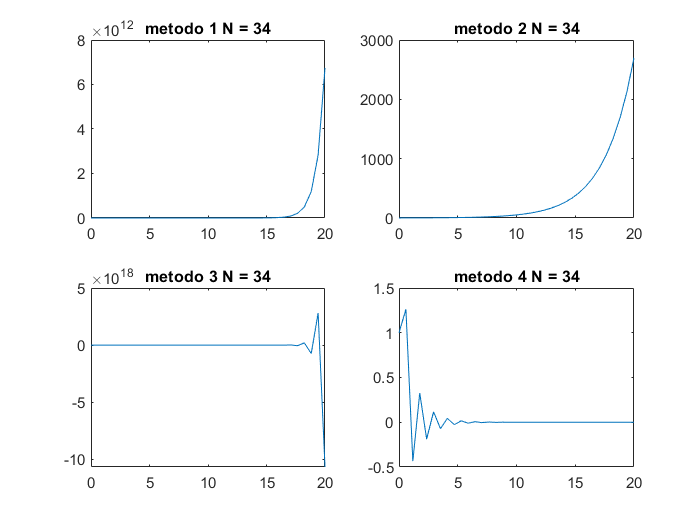

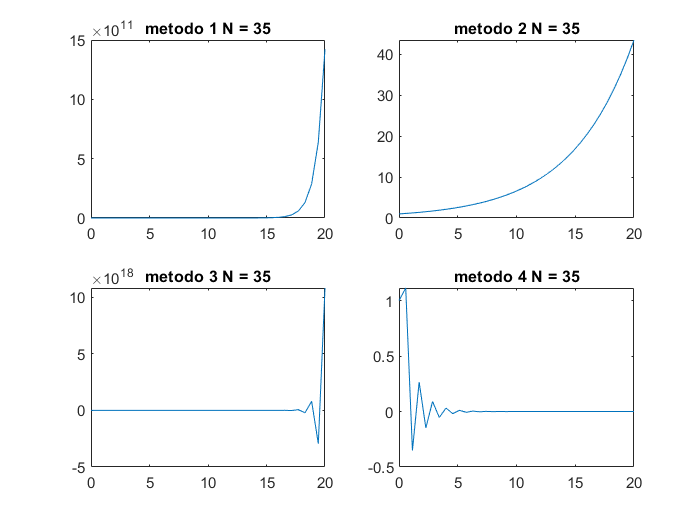

clear all
close all
t0  = 0;
T = 20;
y0 =1;
N = [ 17 30 31 32 33 34 35 36 37 38 39 40];
lambda =-5;
f1 = @(t,y) lambda.*y;
for n = N
    t=[];u=[];
    [t(1,:),u(1,:)]=Heun(f1,t0,T,y0,n);
    [t(2,:),u(2,:)]=RK4(f1,t0,T,y0,n);
    [t(3,:),u(3,:)]=AB2(f1,t0,T,y0,n);
    [t(4,:),u(4,:)]=AM3(f1,t0,T,y0,n);
    figure
    for i=1:4
        subplot(2,2,i)
        plot(t(i,:),u(i,:))
        title("metodo "+i+" N = "+n)
        
    end
end

n = 40;
[t,u] = euleroimp(f1,t0,T,y0,n);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

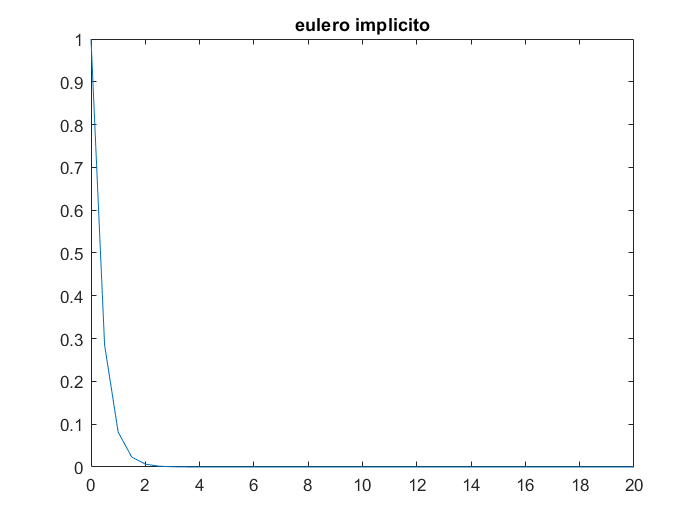

figure 
plot(t,u)
title("eulero implicito")

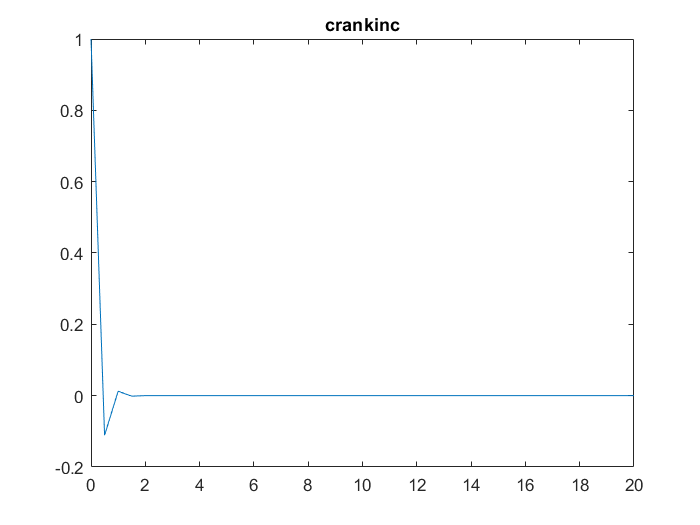

[t,u] = cranknic(f1,t0,T,y0,n);
figure 
plot(t,u)
title("crankinc")

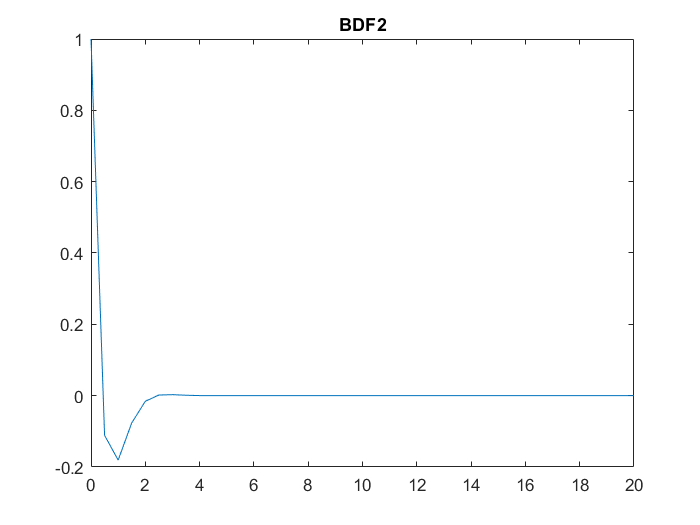

[t,u] = BDF2(f1,t0,T,y0,n);
figure 
plot(t,u)
title("BDF2")